# MOVING MINST

% (C) 2026 Moo K. Chung
% University of Wisconsin
% 
% Last update 2026, Feb 4; 2026 Sept 28
%
% DESCRIPTION
% This dataset contains a compact MATLAB version of the Moving MNIST video
% benchmark. Each sample is a short grayscale video sequence showing one or
% two handwritten MNIST digits undergoing smooth translational motion on a
% 2D grid. The data are intended for studying time-varying image structure,
% motion, geometry, and topology.
%
% SOURCE
% The original Moving MNIST dataset was introduced in:
%
%   Srivastava, N., Mansimov, E., & Salakhudinov, R. (2015).
%   Unsupervised learning of video representations using LSTMs.
%   Proceedings of the 32nd International Conference on Machine Learning (ICML).
%   PMLR, Vol. 37, pp. 843–852.
%
% @inproceedings{srivastava2015unsupervised,
%   title={Unsupervised learning of video representations using lstms},
%   author={Srivastava, Nitish and Mansimov, Elman and Salakhudinov, Ruslan},
%   booktitle={International conference on machine learning},
%   pages={843--852},
%   year={2015},
%   organization={PMLR}
% }
% https://proceedings.mlr.press/v37/srivastava15.pdf
% If you are using data here, please reference this paper. 


% DATA FORMAT
% The variable X is a 4D uint8 array of size:
%
%   X : [64 x 64 x 20 x 1000]
%
% where:
%   - 64 x 64   : spatial resolution (image height x width)
%   - 20        : number of time frames per sequence
%   - 1000      : number of video sequences
%
% Each entry X(:,:,t,n) is a single grayscale image frame at time t from
% sequence n, with intensity values in [0,255].

load moving_mnist_1000

size(X)

ans =           64          64          20        1000


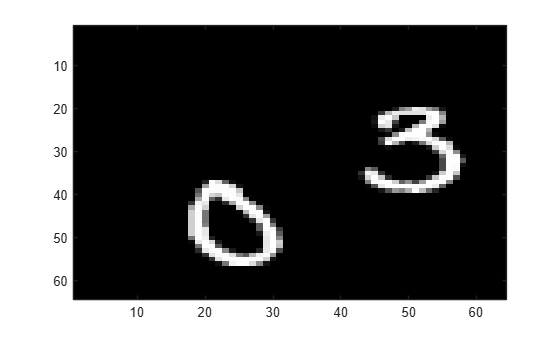


figure; imagesc(X(:,:,10,1));  colormap gray; %10th frame in the first animation

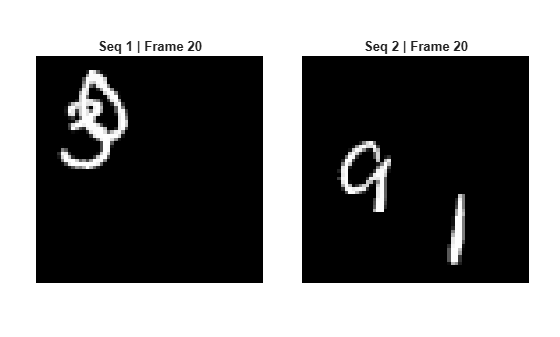

n1 = 1;        % first sequence
n2 = 2;        % second sequence

figure;
tiledlayout(1,2,'Padding','compact','TileSpacing','compact');

for t = 1:size(X,3)
    nexttile(1);
    imagesc(X(:,:,t,n1));
    colormap gray;
    axis image off;
    title(sprintf('Seq %d | Frame %d', n1, t));

    nexttile(2);
    imagesc(X(:,:,t,n2));
    colormap gray;
    axis image off;
    title(sprintf('Seq %d | Frame %d', n2, t));

    drawnow;
end

## Project: Topological clustering of dynamic data

## Goal

The goal of this project is to introduce students to topological representations and distances for high-dimensional image data and time-varying image sequences. Using the Moving MNIST dataset, students will develop principled methods to discretize and represent images algebraically, construct monotone filtrations, and design topology-aware distances that capture geometric and structural differences beyond pixelwise similarity. The project emphasizes understanding how topology evolves under filtration and over time, and how this information can be used for clustering static images and dynamic animations.

Problems

- **Visualize the Moving MNIST data**. Select several Moving MNIST sequences and display their frames as animations. Generate a GIF file for each selected sequence. Can you quantify the speed and accelation of moving digits?

% X(:,:,t,s) is frame t (1..20) of sequence s (1..1000).
[numRows, numCols, numFrames, numSequences] = size(X)  % size of each dimension of X: 64, 64, 20, 1000

numRows = 64

numCols = 64

numFrames = 20

numSequences = 1000

Animation of each chosen sequence (press play under the figure)

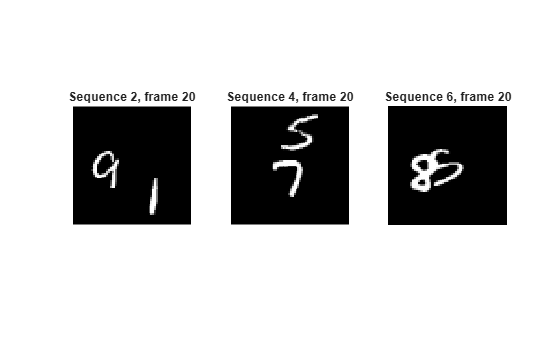

% Animation of the chosen sequences
figure                                              % open a new figure window
chosen = [2 4 6];                                   % the sequences to animate
tiledlayout(1, numel(chosen))                       % 1 row of panels, one panel per sequence
for t = 1:numFrames                                 % loop over time: frame 1 to 20
    for i = 1:numel(chosen)                         % loop over the chosen sequences
        nexttile(i)                                 % go to panel i
        imshow(X(:,:,t,chosen(i)))                  % show frame t of sequence chosen(i)
        title("Sequence " + chosen(i) + ", frame " + t)  % sequence and frame number above the panel
    end                                             
    drawnow                                         % update the figure now: this makes the animation
end                                                 

Speed and acceleration. A digit is a connected component of the binary image: Betti-0 = number of connected components [768-topology.pdf p.17], with 4-neighbor connectivity [768-TDA.pdf p.11]. When Betti-0 = 2 the two digits are apart and digit_positions.m takes the center of each component; otherwise the frame is skipped.

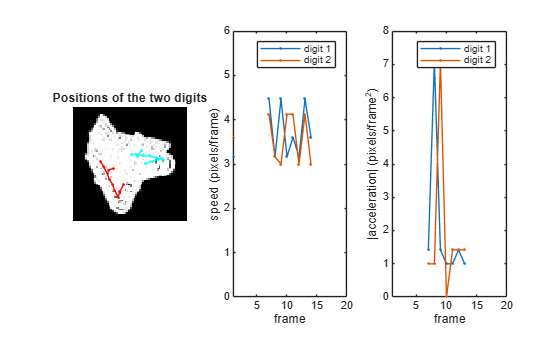

%   velocity     v(t) = c(t+1) - c(t)    (pixels per frame)
%   acceleration a(t) = v(t+1) - v(t)    (pixels per frame^2)
s = 1;                                              % use sequence 1
centers = digit_positions(X(:,:,:,s));              % 20 x 2 x 2: frame, [x y], digit
velocity = diff(centers);                           % 19 x 2 x 2
acceleration = diff(centers, 2);                    % 18 x 2 x 2
speed = squeeze(vecnorm(velocity, 2, 2));           % 19 x 2: length of v for each digit
accelerationSize = squeeze(vecnorm(acceleration, 2, 2));  % 18 x 2: length of a for each digit

figure                                             
tiledlayout(1, 3)                                   
nexttile                                            % panel 1
imshow(max(X(:,:,:,s), [], 3))                      
hold on                                             
plot(centers(:,1,1), centers(:,2,1), "r.-", centers(:,1,2), centers(:,2,2), "c.-")  
title("Positions of the two digits")                
nexttile                                            % panel 2
plot(speed, ".-")                                   
xlim([1 numFrames])                                
ylim([0 6])                                         
xlabel("frame")                                    
ylabel("speed (pixels/frame)")                      
legend("digit 1", "digit 2")                        
nexttile                                            % panel 3
plot(accelerationSize, ".-")                        
xlim([1 numFrames])                                 
xlabel("frame")                                     
ylabel("|acceleration| (pixels/frame^2)")           
legend("digit 1", "digit 2")                        

% (gaps in the curves = frames where Betti-0 is not 2, e.g. the digits touch)

The same measurement for all 1000 sequences

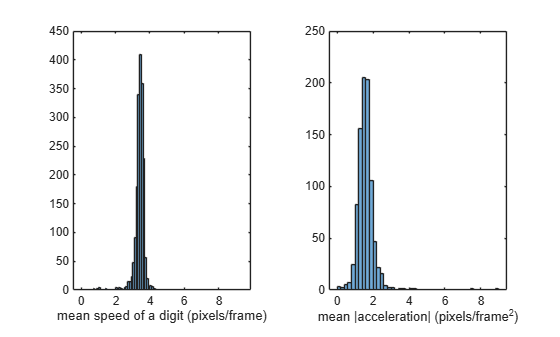

meanSpeed = zeros(numSequences, 2);                 % mean speed of digit 1 and 2, one row per sequence
meanAcceleration = zeros(numSequences, 1);          % mean |acceleration| of each sequence
for s = 1:numSequences                              % loop over all 1000 sequences
    centers = digit_positions(X(:,:,:,s));          % positions of the two digits in the 20 frames
    speed = squeeze(vecnorm(diff(centers), 2, 2));  % 19 x 2: speed of each digit in each frame
    meanSpeed(s, :) = mean(speed, "omitnan");       % average speed, skipping frames with no position (NaN)
    meanAcceleration(s) = mean(vecnorm(diff(centers, 2), 2, 2), "all", "omitnan");  % average |acceleration| of both digits
end                                                 

figure                                              
tiledlayout(1, 2)                                   
nexttile                                            % panel 1
histogram(meanSpeed)                                
xlabel("mean speed of a digit (pixels/frame)")     
nexttile                                            % panel 2
histogram(meanAcceleration)                         
xlabel("mean |acceleration| (pixels/frame^2)")      


fprintf("Mean speed: %.2f pixels/frame\n", mean(meanSpeed(:), "omitnan"));  

Mean speed: 3.40 pixels/frame


fprintf("Mean |acceleration|: %.2f pixels/frame^2\n", mean(meanAcceleration, "omitnan"));  

Mean |acceleration|: 1.59 pixels/frame^2



% Result: digits moves at about 3.40 pixels/frame 

% The acceleration is about 1.59 pixel/frame^2.


**2. Construct a filtration.** Select one grayscale image and construct either a graph-based or image-based filtration. Choose filtration values so that the resulting objects form a nested sequence. Display the filtration and verify that pixels, nodes, or edges are only added, or only removed, as the filtration value changes.

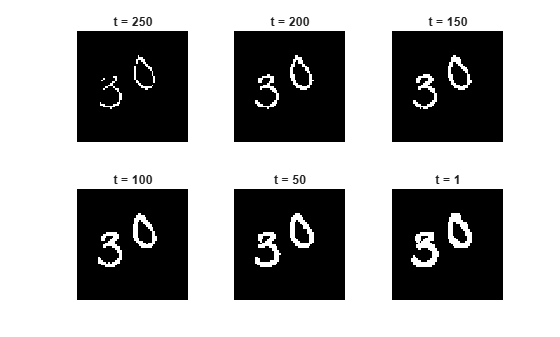

% A filtration is a nested sequence K1 subset K2 subset ... [768-TDA.pdf p.12]
% Thresholding gives one: if t1 >= t2, every pixel with I >= t1 also has I >= t2.
%
% (A) Image-based: a 2D image is a cubical complex, with 4-neighbor connectivity
%     [768-TDA.pdf p.11]. K_t = {pixels with I >= t}, t = 255 ... 0.
%     The bright strokes appear first and the black background last:
%     pixels are only ADDED as t decreases.

% (B) Graph-based: graph filtration on a weighted graph X = (V, w), keeping the
%     edges with weight > eps for increasing eps: X_eps0 > X_eps1 > ...
%     [768-TDA.pdf p.17]. Nodes = pixels, edges = 4-neighbor pixels, I choose edge
%     weight = min of the two pixel values. Edges are only
%     REMOVED as eps increases; the nodes never change.

I = X(:,:,1,1);                                     % sequence 1, frame 1: digits 3 and 0

% (A) Image-based filtration at a few thresholds
thresholds = [250 200 150 100 50 1];                % the thresholds t to show
figure                                              
tiledlayout(2, 3)                                   
for k = 1:numel(thresholds)                         % loop over the 6 thresholds
    nexttile                                        
    imshow(I >= thresholds(k))                      % show K_t: white = pixels with I >= t
    title("t = " + thresholds(k))                   % the threshold above the panel
end                                                 

Check (A): every level is inside the next one, and the number of pixels never decreases

isNested = true;                                    % becomes false if a level is not inside the next one
numPixels = zeros(1, 256);                          % number of pixels of K_t for t = 255, 254, ..., 0
for t = 255:-1:0                                    % go down through all thresholds
    K = I >= t;                                     % this level
    Knext = I >= t - 1;                             % next level
    if any(K & ~Knext, "all")                       % a pixel of K missing in the next level?
        isNested = false;                           % the filtration is not nested
    end                                             
    numPixels(256 - t) = nnz(K);                    % count the pixels of K_t (nnz = number of nonzeros)
end                                                 
isNested                                            %  1 = true

isNested = logical
   1


pixelsNeverDecrease = all(diff(numPixels) >= 0)     % true if the number of pixels never goes down

pixelsNeverDecrease = logical
   1


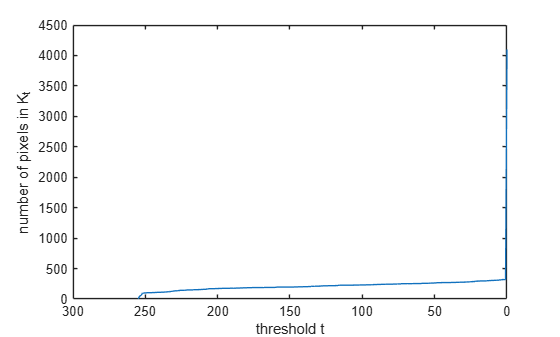


figure                                             
plot(255:-1:0, numPixels)                           % number of pixels against the threshold
set(gca, "XDir", "reverse")                         % t decreases from left to right
xlabel("threshold t")                               
ylabel("number of pixels in K_t")                   

(B) Graph-based filtration at a few values of eps (red = edges still present)

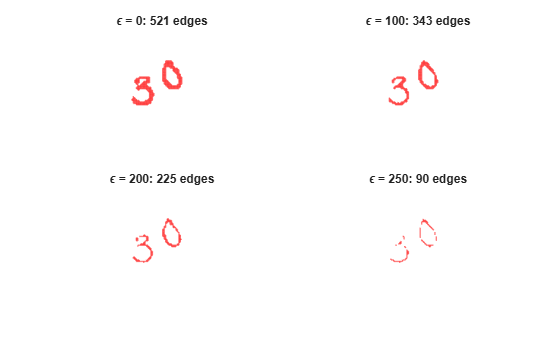

[G, births, deaths] = graph_filtration(I);          % graph of the image, its births and deaths
[y, x] = ind2sub(size(I), 1:numnodes(G));          % pixel position of every node

epsValues = [0 100 200 250];                        % the values of eps to show
figure                                              
tiledlayout(2, 2)                                   
for k = 1:numel(epsValues)                          % loop over the 4 values of eps
    Geps = rmedge(G, find(G.Edges.Weight <= epsValues(k)));  % remove the edges with weight <= eps
    nexttile                                        
    plot(Geps, "XData", x, "YData", y, "NodeColor", "none", "EdgeColor", "r");  % draw the edges at the pixel positions
    set(gca, "YDir", "reverse")                     % row 1 at the top, like an image
    axis equal off                                  % same scale on both axes, no axis lines
    title("\epsilon = " + epsValues(k) + ": " + numedges(Geps) + " edges")  % eps and the number of edges left
end                                                 

Check (B): when eps increases no edge is ever added, and the nodes stay the same

isNested = true;                                    % becomes false if an edge ever appears
numEdges = zeros(1, 256);                           % number of edges of G_eps for eps = 0..255
for epsilon = 0:255                                 % go up through all values of eps
    keepNow = G.Edges.Weight > epsilon;             % edges kept at this eps (true/false per edge)
    keepNext = G.Edges.Weight > epsilon + 1;        % edges kept at the next eps
    if any(keepNext & ~keepNow)                     % an edge that appears?
        isNested = false;                           % the filtration is not nested
    end                                             
    numEdges(epsilon + 1) = sum(keepNow);           % count the edges kept at this eps
end                                                 
isNested                                            

isNested = logical
   1


edgesNeverIncrease = all(diff(numEdges) <= 0)       % true if the number of edges never goes up

edgesNeverIncrease = logical
   1


numberOfNodes = numnodes(G)                         % the nodes (pixels) never change: always 4096

numberOfNodes = 4096

**3. Topological features from the filtration**. Using the filtration, compute Betti-0 and Betti-1 at every threshold. Identify when connected components appear or merge and when holes appear or disappear. Plot the Betti curves and summarize the topology of the image across the filtration. Design a filtration such taht Betti-0 and Betti-1 are monotone.  

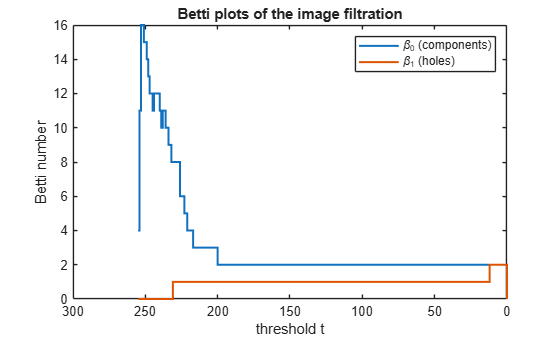

% Betti-0 = number of connected components, Betti-1 = number of 1D holes,
% Euler characteristic chi = Betti-0 - Betti-1 [768-topology.pdf p.17].

% betti_curves counts the components with bwconncomp (built-in function of Image Processing Toolbox)
% and 
% computes the Euler characteristic of the binary image with bweuler (built-in function of Image Processing Toolbox) 
% [768-topology.pdf p.14],

% so Betti-1 = Betti-0 - chi.

% Going down from t = 255 to 0 in the image filtration:
%   Betti-0 goes up when a new bright spot appears (a component is born)
%           and down when two components touch (they merge);
%   Betti-1 goes up when a stroke closes a loop (a hole is born)
%           and down when the hole is filled in.
% So the Betti plots of the image filtration are NOT monotone: nestedness does
% not imply monotone Betti numbers [768-TDA.pdf p.13].
thresholds = 255:-1:0;                              % every threshold, from 255 down to 0
[beta0, beta1] = betti_curves(I, thresholds);       % Betti-0 and Betti-1 of K_t at every threshold

figure                                              
stairs(thresholds, beta0, "LineWidth", 1.5)         % Betti-0 plot 
hold on                                             
stairs(thresholds, beta1, "LineWidth", 1.5)         % Betti-1 plot
set(gca, "XDir", "reverse")                         
xlabel("threshold t")                               
ylabel("Betti number")                              
legend("\beta_0 (components)", "\beta_1 (holes)")   
title("Betti plots of the image filtration")        

When do components appear / merge and holes appear / disappear? Each row is a threshold where a Betti number changes.

k = find(diff(beta0) ~= 0 | diff(beta1) ~= 0);      % positions where Betti-0 or Betti-1 changes
events = table(thresholds(k+1)', beta0(k)', beta0(k+1)', beta1(k)', beta1(k+1)', ...
    'VariableNames', ["t", "beta0 before", "beta0 after", "beta1 before", "beta1 after"])  % table: threshold, Betti numbers before and after

events = 22×5 table
     t     beta0 before    beta0 after    beta1 before    beta1 after
    ___    ____________    ___________    ____________    ___________

    254          4             11              0               0     
    253         11             16              0               0     
    251         16             15              0               0     
    249         15             14              0               0     
    248         14             13              0               0     
    247         13             12              0               0     
    245         12             11              0               0     
    244         11             12              0               0     
    240         12             11              0               0     
    239         11             10      


% Summary: features detected over a wide range of thresholds are true
% features, short-lived ones are noise [768-TDA.pdf p.7].
% persistent_betti.m keeps the Betti numbers that last the longest over the whole range of thresholds.
[numComponents, numHoles] = persistent_betti(I)     % the Betti numbers that last the longest

numComponents = 2

numHoles = 1


% Result for this image (digits 3 and 0):
%   t = 254..232 : many very bright spots appear and merge (noise inside the strokes)
%   t = 231      : the loop of the 0 closes, beta1 = 1 (a hole is born)
%   t = 226..200 : the last pieces merge, beta0 = 2 at t = 200 (one component per digit)
%   t = 12       : faint pixels of the 3 close a small loop (short-lived hole)
%   t = 0        : the black background enters: one component, all holes filled
% The persistent Betti numbers are 2 components and 1 hole: the digits 3 and 0.

A filtration with MONOTONE Betti plots: use a more structured filtration [768-TDA.pdf p.14], the graph filtration of problem 2. Deleting an edge increases Betti-0 by 0 or 1 [768-TDA.pdf p.24] and decreases Betti-1 by 0 or 1 [768-TDA.pdf p.27], so the Betti plots over a graph filtration are monotone [768-TDA.pdf p.29]. Computation [768-TDA.pdf p.30]: Betti-0 = number of connected components (conncomp is default builtt-in func of MATLAB), and with p nodes and q edges, Betti-1 = Betti-0 - p + q.

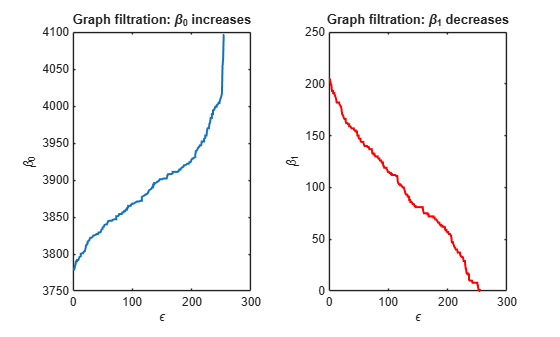

epsValues = 0:255;                                  % every value of eps
beta0Graph = zeros(size(epsValues));                % Betti-0 of G_eps for each eps
beta1Graph = zeros(size(epsValues));                % Betti-1 of G_eps for each eps
for k = 1:numel(epsValues)                          % loop over eps
    Geps = rmedge(G, find(G.Edges.Weight <= epsValues(k)));  % G_eps: remove the edges with weight <= eps
    p = numnodes(Geps);                             % p = number of nodes
    q = numedges(Geps);                             % q = number of edges
    beta0Graph(k) = max(conncomp(Geps));            % number of connected components
    beta1Graph(k) = beta0Graph(k) - p + q;          % number of cycles: Betti-1 = Betti-0 - p + q
end                                                 

figure                                              
tiledlayout(1, 2)                                   
nexttile                                           
stairs(epsValues, beta0Graph, "LineWidth", 1.5)     % Betti-0 plot of the graph filtration
xlabel("\epsilon")                                  
ylabel("\beta_0")                                   
title("Graph filtration: \beta_0 increases")        
nexttile                                            
stairs(epsValues, beta1Graph, "r", "LineWidth", 1.5)  % Betti-1 plot of the graph filtration
xlabel("\epsilon")                                  
ylabel("\beta_1")                                   
title("Graph filtration: \beta_1 decreases")        


isMonotone = all(diff(beta0Graph) >= 0) && all(diff(beta1Graph) <= 0)  % true if Betti-0 never goes down and Betti-1 never goes up

isMonotone = logical
   1



% Birth and death sets [768-TDA.pdf p.33-34]: the edges of the maximum spanning
% tree are the births (deleting them creates components), the other edges are
% the deaths (deleting them destroys cycles). They partition the edge set and
% give the same Betti plots:
%   Betti-0(eps) = 1 + #{births <= eps},   Betti-1(eps) = #{deaths > eps}
numBirths = numel(births)                           % number of birth edges (maximum spanning tree)

numBirths = 4095

numDeaths = numel(deaths)                           % number of death edges (all other edges)

numDeaths = 3969

sameAsBirthDeath = isequal(beta0Graph, 1 + sum(births' <= epsValues)) && ...
                   isequal(beta1Graph, sum(deaths' > epsValues))  % true if births/deaths give the same Betti plots

sameAsBirthDeath = logical
   1



% The price of monotonicity: the graph Betti-1 counts every small square cycle
% of the pixel grid, and Betti-0 counts every isolated background pixel, so
% they are not the holes of the digits.

**4. Topological distance between images****. **Use the topological features to define a distance between two image frames. Test the distance on many pairs of images. Determine whether distances between topologically similar images are generally smaller than distances between topologically different images. Compare this behavior with pixelwise Euclidean distance. 

% Geometric distance vs. topological distances [768-wasserstein.pdf p.2].
% frame_distances.m computes three distances between two frames A and B:
%   dGeo  : geometric distance = pixelwise Euclidean distance
%   dTop  : difference in topology = |change in # components| + |change in # holes|
%           of the persistent Betti numbers. Same idea as d_top in
%           [768-wasserstein.pdf p.2]: a circle and a square have d_top = 0,
%           a broken circle and a circle have d_top = 1.
%   dWass : 2-Wasserstein distance between the graph filtrations
%           [768-wasserstein.pdf p.13-14]: the i-th smallest birth of A is
%           matched with the i-th smallest birth of B, and the same for deaths.
%
% There are no digit labels, so I build tests where I know which pairs are
% similar

% TEST 1: frames t and t+5 of the SAME sequence show the same digits, shifted
% by ~17 pixels: same topology, but the pixels hardly overlap. Each "similar"
% pair is compared with a "different" pair: random frames of two random
% sequences. A good distance gives the similar pair the smaller distance.
rng(1)                                              % same random pairs every run
numPairs = 300;                                     % number of similar pairs and of different pairs
distGeo = zeros(numPairs, 2);                       % column 1: similar, column 2: different
distTop = zeros(numPairs, 2);                       % same for d_top
distWass = zeros(numPairs, 2);                      % same for the Wasserstein distance
for p = 1:numPairs                                  % loop over the pairs
    % similar pair: frames t and t+5 of the same sequence
    s = randi(numSequences);                        % a random sequence
    t = randi(numFrames - 5);                       % a random frame t (t+5 must exist)
    [distGeo(p,1), distTop(p,1), distWass(p,1)] = frame_distances(X(:,:,t,s), X(:,:,t+5,s));  % 3 distances between frames t and t+5

    % different pair: random frames of two random sequences
    s1 = randi(numSequences);                       % first random sequence
    s2 = randi(numSequences);                       % second random sequence
    [distGeo(p,2), distTop(p,2), distWass(p,2)] = ...
        frame_distances(X(:,:,randi(numFrames),s1), X(:,:,randi(numFrames),s2));  % 3 distances between random frames of s1 and s2
end                                                 % end of the loop over pairs

% Fraction of the 300 comparisons where the similar pair is closer
% (a tie counts as one half; 1 = always closer, 0.5 = like flipping a coin)
distance = ["geometric (Euclidean)"; "d_top (Betti numbers)"; "Wasserstein (graph filtration)"];  % names of the distances
closer = @(d) mean(d(:,1) < d(:,2)) + 0.5 * mean(d(:,1) == d(:,2));  % function: fraction where column 1 < column 2
similarIsCloser = [closer(distGeo); closer(distTop); closer(distWass)];  % this fraction for each distance
meanSimilar = [mean(distGeo(:,1)); mean(distTop(:,1)); mean(distWass(:,1))];  % mean distance of the similar pairs
meanDifferent = [mean(distGeo(:,2)); mean(distTop(:,2)); mean(distWass(:,2))];  % mean distance of the different pairs
test1 = table(distance, meanSimilar, meanDifferent, similarIsCloser)  % show the results as a table

test1 = 3×4 table
                distance                meanSimilar    meanDifferent    similarIsCloser
    ________________________________    ___________    _____________    _______________

    "geometric (Euclidean)"                4317.4         4403.4            0.54333    
    "d_top (Betti numbers)"               0.65333         1.6233            0.74167    
    "Wasserstein (graph filtration)"        175.2         1316.8            0.96333    

	Get insights using Copilot


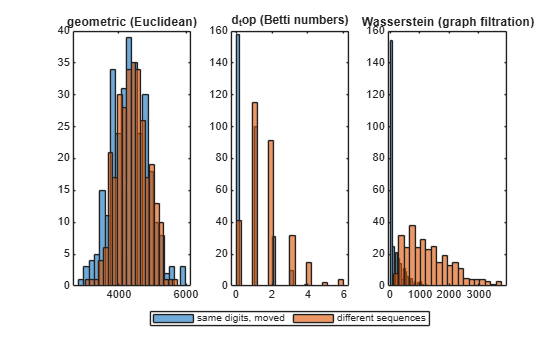


figure                                              % new figure
tiledlayout(1, 3)                                   % 3 panels side by side
allDistances = {distGeo, distTop, distWass};        % the 3 kinds of distances in a cell array
for m = 1:3                                         % loop over the 3 distances
    d = allDistances{m};                            % 300 x 2 distances of this kind
    nexttile                                        % next panel
    histogram(d(:,1), 20)                           % histogram of the similar pairs (20 bins)
    hold on                                         % draw the next histogram on top
    histogram(d(:,2), 20)                           % histogram of the different pairs
    title(distance(m))                              % name of the distance above the panel
end                                                 % end of the loop over distances
lgd = legend("same digits, moved", "different sequences", "Orientation", "horizontal");  % one legend for the two colors
lgd.Layout.Tile = "south";                          % one legend below the three plots

%TEST 2: each frame gets a topological class = (persistent # components, persistent # holes). 
% Are frames of the same class closer than frames of different classes? 
% (d_top is 0 for the same class by definition, so we only test the geometric and the Wasserstein distances here.)

numImages = 300;                                    % number of random frames
pixels = zeros(numImages, numRows * numCols);       % one row of 4096 pixel values per frame
graphVectors = zeros(numImages, 8064);              % 4095 births + 3969 deaths
classes = zeros(numImages, 2);                      % persistent [# components, # holes] of each frame
for k = 1:numImages                                 % loop over the frames
    img = X(:,:,randi(numFrames),randi(numSequences));  % a random frame of a random sequence
    pixels(k,:) = double(img(:))';                  % the image as one row
    [~, birthsK, deathsK] = graph_filtration(img);  % sorted births and deaths of its graph filtration
    graphVectors(k,:) = [birthsK deathsK];          % store them as one row
    [classes(k,1), classes(k,2)] = persistent_betti(img);  % its topological class
end                                                 % end of the loop over frames

% pdist gives the Euclidean distance of every pair of rows. For the sorted
% [births deaths] vectors this is exactly the 2-Wasserstein distance
% [768-wasserstein.pdf p.14]. Two frames have the same class when the
% distance between their classes is 0.
sameClass = pdist(classes) == 0;                    % true for each pair of frames with the same class
dGeo = pdist(pixels);                               % Euclidean distance of every pair of frames
dWass = pdist(graphVectors);                        % Wasserstein distance of every pair of frames

distance = ["geometric (Euclidean)"; "Wasserstein (graph filtration)"];  % names of the distances
meanSameClass = [mean(dGeo(sameClass)); mean(dWass(sameClass))];  % mean distance within the same class
meanDifferentClass = [mean(dGeo(~sameClass)); mean(dWass(~sameClass))];  % mean distance between different classes
ratio = meanSameClass ./ meanDifferentClass;        % < 1: same class is closer
test2 = table(distance, meanSameClass, meanDifferentClass, ratio)  % show the results as a table

test2 = 2×4 table
                distance                meanSameClass    meanDifferentClass     ratio 
    ________________________________    _____________    __________________    _______

    "geometric (Euclidean)"                  4373              4439.2          0.98508
    "Wasserstein (graph filtration)"       1205.4              1281.2           0.9408

	Get insights using Copilot


% Result:
% - Geometric (Euclidean): the similar pair is closer in only 54% of the
%   comparisons. Once the digits move, their pixels no
%   longer overlap, so "same digits" looks as far away as "other digits".

% - d_top: 74%. Its mean is 0.65 for "same digits" and 1.62 for "different".
%   It is not 0 for every "same digits" pair because in one of the two frames
%   the digits may touch (1 component instead of 2, sometimes extra holes).

% - Wasserstein: 96% in test 1, because the sorted births and deaths do not
%   change when the image is shifted. But in test 2 the ratio is only 0.94:
%   frames with the same (# components, # holes) are hardly closer. The graph
%   cycles are the small squares of the pixel grid, not the holes of the digits.


**5. Cluster static image frames****.** Use the topological distance to cluster individual image frames. Examine representative images from each cluster and determine what topological properties characterize each group. Compare the clustering with results obtained using pixelwise or Euclidean distance.

% Topological clustering with the Wasserstein distance [768-PH-STAT.pdf p.6].
% The topological mean of several graph filtrations is the minimizer of the
% topological distance: average the sorted MST edge weights (births) and the
% sorted non-MST edge weights (deaths) separately [768-wasserstein.pdf p.18].

% Clustering repeats two steps:
%   1. put each frame in the cluster with the closest topological mean
%      (2-Wasserstein distance [768-wasserstein.pdf p.14])
%   2. recompute the topological mean of each cluster

% The idea of this is somewhat similar to kmeans

% Baseline (geometric): the same two steps on the pixels.

rng(2)                                              % same random frames every run
numImages = 400;                                    % number of random frames to cluster
images = zeros(numRows, numCols, numImages, "uint8");  % the frames themselves
graphVectors = zeros(numImages, 8064);              % sorted [births deaths] of each frame
pixels = zeros(numImages, numRows * numCols);       % pixel values of each frame (one row each)
numComponents = zeros(numImages, 1);                % persistent # components of each frame
numHoles = zeros(numImages, 1);                     % persistent # holes of each frame
graphBeta0 = zeros(numImages, 1);                   % graph Betti-0 at eps = 30 of each frame
centerX = zeros(numImages, 1);                      % x of the center of brightness
centerY = zeros(numImages, 1);                      % y of the center of brightness
for k = 1:numImages                                 % loop over the frames
    img = X(:,:,randi(numFrames),randi(numSequences));  % a random frame of a random sequence
    images(:,:,k) = img;                            % store the frame
    [~, birthsK, deathsK] = graph_filtration(img);  % sorted births and deaths of its graph filtration
    graphVectors(k,:) = [birthsK deathsK];          % store them as one row
    pixels(k,:) = double(img(:))';                  % the image as one row
    [numComponents(k), numHoles(k)] = persistent_betti(img);  % its persistent Betti numbers
    % Betti-0 of the graph filtration at eps = 30 [768-TDA.pdf p.29, p.33]:
    % 1 + #{births <= 30}. Small = many pixels are joined into the strokes.
    graphBeta0(k) = 1 + sum(birthsK <= 30);         % Betti-0 of G_eps at eps = 30
    % where the digits are (center of the brightness)
    stats = regionprops(true(numRows, numCols), double(img), "WeightedCentroid");  % center of the image, weighted by brightness
    centerX(k) = stats.WeightedCentroid(1);         % x coordinate of the center
    centerY(k) = stats.WeightedCentroid(2);         % y coordinate of the center
end                                                 % end of the loop over frames

% Topological class of each frame, e.g. "2 comp, 1 holes"
topoClass = string(numComponents) + " comp, " + string(numHoles) + " holes";  % text label of the class of each frame

% Number of clusters k = number of common topological classes, i.e. classes
% with at least 5% of the frames (statistically significant choice)
classCounts = groupcounts(topoClass);               % number of frames in each class
k = sum(classCounts >= 0.05 * numImages)            % number of classes with at least 5% of the frames

k = 6


clusterTopo = kmeans(graphVectors, k, "Replicates", 10);  % topological clusters (10 random starts, keep the best)
clusterGeo = kmeans(pixels, k, "Replicates", 10);   % geometric clusters of the pixels

Examples from each topological cluster: row c shows 10 frames of cluster c

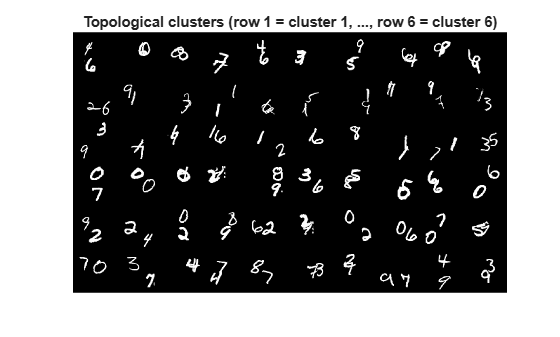

examples = zeros(numRows, numCols, 1, 10 * k, "uint8");  % 10 frames per cluster, for the montage
for c = 1:k                                         % loop over the clusters
    members = find(clusterTopo == c, 10);           % first 10 members of cluster c
    examples(:,:,1,(c-1)*10 + (1:numel(members))) = images(:,:,members);  % put them in row c
end                                                 % end of the loop over clusters
figure                                              % new figure
montage(examples, "Size", [k 10]);                  % show them in k rows of 10
title("Topological clusters (row 1 = cluster 1, ..., row " + k + " = cluster " + k + ")")  % title of the plot

Examples from each geometric (Euclidean) cluster

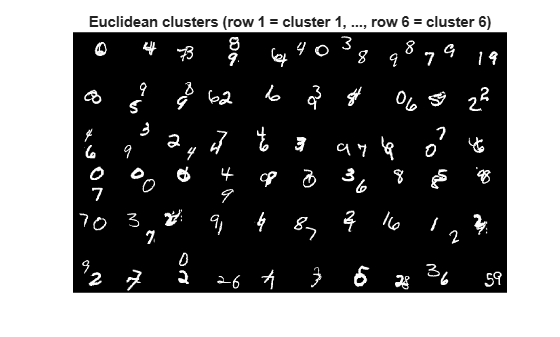

examples = zeros(numRows, numCols, 1, 10 * k, "uint8");  % 10 frames per cluster, for the montage
for c = 1:k                                         % loop over the clusters
    members = find(clusterGeo == c, 10);            % first 10 members of cluster c
    examples(:,:,1,(c-1)*10 + (1:numel(members))) = images(:,:,members);  % put them in row c
end                                                 % end of the loop over clusters
figure                                              % new figure
montage(examples, "Size", [k 10]);                  % show them in k rows of 10
title("Euclidean clusters (row 1 = cluster 1, ..., row " + k + " = cluster " + k + ")")  % title of the plot

What characterizes each cluster? Mean topology (persistent Betti numbers, graph Betti-0 at eps = 30) and mean position of the frames of each cluster

T = table(clusterTopo, clusterGeo, topoClass, numComponents, numHoles, graphBeta0, centerX, centerY);  % one row per frame with all its measurements
groupsummary(T, "clusterTopo", "mean", ["numComponents", "numHoles", "graphBeta0", "centerX", "centerY"])  % mean of each measurement in each topological cluster

ans = 6×7 table
    clusterTopo    GroupCount    mean_numComponents    mean_numHoles    mean_graphBeta0    mean_centerX    mean_centerY
    ___________    __________    __________________    _____________    _______________    ____________    ____________

         1            104              1.5865                1.25           3827.7            33.218          33.861   
         2             25                1.76                0.24           3935.9            31.063          35.597   
         3             81              1.7037             0.61728           3887.4            33.339          32.432   
         4             27              1.7778              1.4815           3743.4            33.741          30.796   
         5             68

groupsummary(T, "clusterGeo", "mean", ["numComponents", "numHoles", "graphBeta0", "centerX", "centerY"])  % same for the Euclidean clusters

ans = 6×7 table
    clusterGeo    GroupCount    mean_numComponents    mean_numHoles    mean_graphBeta0    mean_centerX    mean_centerY
    __________    __________    __________________    _____________    _______________    ____________    ____________

        1             95              1.6526             0.86316           3843.7            42.418          31.664   
        2             65              1.6769              1.0615           3837.2            32.615          33.372   
        3             75              1.6267              1.0533           3843.2            24.969          38.228   
        4             42              1.7381              1.3571             3815            34.782          25.611   
        5             72       


% Which grouping does each clustering follow?
% Purity = fraction of frames that belong to the most common group of their
% cluster (1 = every cluster contains a single group). Groups:
%   topoClass  : persistent (# components, # holes)
%   strokeSize : graph Betti-0 at eps = 30 in 3 equal-size groups (small/medium/large)
%   position   : which quarter of the image holds the brightness
T.strokeSize = discretize(graphBeta0, quantile(graphBeta0, [0 1/3 2/3 1]));  % 3 groups: small / medium / large strokes
T.position = string(centerX > 32) + "/" + string(centerY > 32);  % quarter of the image: right? / down?
purity = @(clusters, groups) sum(max(crosstab(clusters, groups), [], 2)) / numel(clusters);  % function: purity of a clustering for a grouping

clustering = ["topological (Wasserstein)"; "geometric (Euclidean)"];  % names of the two clusterings
purityTopoClass = [purity(clusterTopo, topoClass); purity(clusterGeo, topoClass)];  % purity for the topological class
purityStrokeSize = [purity(clusterTopo, T.strokeSize); purity(clusterGeo, T.strokeSize)];  % purity for the stroke size
purityPosition = [purity(clusterTopo, T.position); purity(clusterGeo, T.position)];  % purity for the position
table(clustering, purityTopoClass, purityStrokeSize, purityPosition)  % show the results as a table

ans = 2×4 table
            clustering             purityTopoClass    purityStrokeSize    purityPosition
    ___________________________    _______________    ________________    ______________

    "topological (Wasserstein)"        0.2875              0.8175              0.31     
    "geometric (Euclidean)"              0.26               0.405             0.625     

	Get insights using Copilot


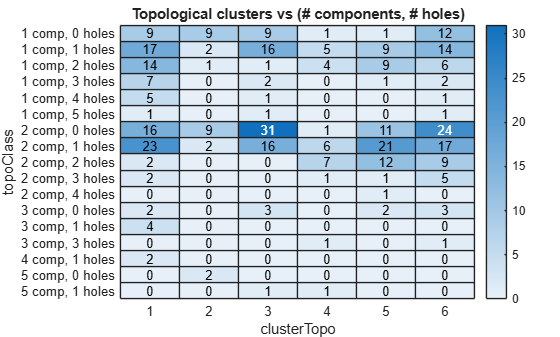


figure                                              % new figure
heatmap(T, "clusterTopo", "topoClass");             % number of frames of each class in each cluster
title("Topological clusters vs (# components, # holes)")  % title of the plot

A 2D map of the frames: multidimensional scaling [768-wasserstein.pdf p.21] of the Wasserstein distances and of the Euclidean distances

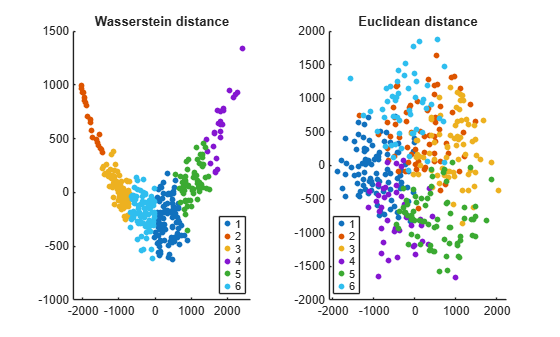

Ytopo = cmdscale(squareform(pdist(graphVectors)), 2);  % 2D points that keep the Wasserstein distances
Ygeo = cmdscale(squareform(pdist(pixels)), 2);      % 2D points that keep the Euclidean distances
figure                                              % new figure
tiledlayout(1, 2)                                   % 2 panels side by side
nexttile                                            % panel 1
gscatter(Ytopo(:,1), Ytopo(:,2), clusterTopo)       % one dot per frame, colored by its cluster
title("Wasserstein distance")                       % title of panel 1
nexttile                                            % panel 2
gscatter(Ygeo(:,1), Ygeo(:,2), clusterGeo)          % same for the Euclidean clusters
title("Euclidean distance")                         % title of panel 2


% Result (k = 6):
% - The topological (Wasserstein) clusters are ordered by the graph Betti-0 at
%   eps = 30, i.e. by how many pixels are joined into the strokes: from small
%   strokes (graph Betti-0 about 3940, few holes 0.24) to large strokes (about
%   3740, more holes 1.48). Purity for the stroke size: 0.82. Their mean center
%   is near the middle of the image for every cluster.

% - The geometric (Euclidean) clusters all have the same topology on average
%   but very different centers (x from 25 to 42, y from 26 to 41): they group
%   the frames by WHERE the digits are (purity for the position 0.63).

% - Neither clustering follows the (# components, # holes) class well (purity
%   0.29 and 0.26): the Wasserstein distance on the graph filtration measures
%   the 0D topology of the strokes, not the holes of the digits (problem 4).

**6. Cluster dynamic images****.** Treat each frame sequence as one dynamic object. Develop a distance between two animations that accounts for how their topology changes over time. Use this distance to cluster animations. Determine whether the resulting groups are associated with digit topology.

% A sequence is described by the topology of its 20 frames, in time order.
% Two distances between animations A and B that follow how the topology
% changes over time:

%   Wasserstein over time : sqrt( sum over frames t of W(A_t, B_t)^2 ), where
%       W is the 0D part of the 2-Wasserstein distance between the graph
%       filtrations (matching sorted births = maximum spanning tree edges)
%       [768-wasserstein.pdf p.14]. We use only the births (0D topology) to
%       keep the data small. This is the Euclidean distance between the sorted
%       births of frame 1, frame 2, ..., frame 20 put one after the other.

%   d_top over time       : sum over frames t of d_top(A_t, B_t), the change in
%       persistent # components and # holes [768-wasserstein.pdf p.2].
rng(3)                                              % same random sequences every run
numSeqUsed = 200;                                   % number of sequences to cluster
chosenSeq = randperm(numSequences, numSeqUsed);     % 200 different random sequences
birthsOverTime = zeros(numSeqUsed, numFrames * 4095);  % sorted births of the 20 frames, one after the other
numComp = zeros(numSeqUsed, numFrames);             % persistent # components of each frame
numHol = zeros(numSeqUsed, numFrames);              % persistent # holes of each frame
graphBeta0 = zeros(numSeqUsed, 1);                  % mean graph Betti-0 at eps = 30 (stroke size)
for i = 1:numSeqUsed                                % loop over the sequences
    for t = 1:numFrames                             % loop over the frames
        img = X(:,:,t,chosenSeq(i));                % frame t of sequence i
        [~, birthsT] = graph_filtration(img);       % sorted births of its graph filtration
        birthsOverTime(i, (t-1)*4095 + (1:4095)) = birthsT;  % put them in the block of frame t
        [numComp(i,t), numHol(i,t)] = persistent_betti(img);  % its persistent Betti numbers
        % graph Betti-0 at eps = 30, averaged over the frames (stroke size)
        graphBeta0(i) = graphBeta0(i) + (1 + sum(birthsT <= 30)) / numFrames;  % add this frame's share of the average
    end                                             % end of the loop over frames
end                                                 % end of the loop over sequences

% Digit topology of each sequence (only used to evaluate the clusters): 
% total number of holes of its two digits (0 holes: 1 2 3 5 7;
% 1 hole: 0 6 9 and often 4; 2 holes: 8), counted in frames where the digits
% are apart (2 components).
digitHoles = zeros(numSeqUsed, 1);                  % total # holes of the two digits of each sequence
for i = 1:numSeqUsed                                % loop over the sequences
    apart = numComp(i,:) == 2;                      % frames where the two digits are apart
    if any(apart)                                   % if there is at least one such frame
        digitHoles(i) = median(numHol(i, apart));   % typical # holes in those frames
    else                                            % otherwise
        digitHoles(i) = median(numHol(i,:));        % typical # holes in all frames
    end                                             % end of the if
end                                                 % end of the loop over sequences
digitHoles = min(round(digitHoles), 3);             % 0, 1, 2 or 3 (= 3 or more)
tabulate(digitHoles)                                % how many sequences in each hole class

  Value    Count   Percent
      0       79     39.50%
      1       83     41.50%
      2       32     16.00%
      3        6      3.00%


Topological clustering of the animations with topological means [768-wasserstein.pdf p.18] of the births over time (k = 4, the number of hole classes)

k = 4;                                              % number of clusters
[clusterTopo, ~, ~, distToMean] = kmeans(birthsOverTime, k, "Replicates", 10);  % clusters, and distance to each topological mean
clusterSizes = groupcounts(clusterTopo)'            % number of sequences in each cluster

clusterSizes =     62    47    17    74



% What characterizes each cluster? (stroke size = graph Betti-0 at eps = 30)
T = table(clusterTopo, digitHoles, graphBeta0, mean(numComp, 2), mean(numHol, 2), ...
    'VariableNames', ["clusterTopo", "digitHoles", "graphBeta0", "meanComponents", "meanHoles"]);  % one row per sequence
groupsummary(T, "clusterTopo", "mean", ["digitHoles", "graphBeta0", "meanComponents", "meanHoles"])  % mean of each measurement in each cluster

ans = 4×6 table
    clusterTopo    GroupCount    mean_digitHoles    mean_graphBeta0    mean_meanComponents    mean_meanHoles
    ___________    __________    _______________    _______________    ___________________    ______________

         1             62            0.46774            3896.4               1.8758               0.5379    
         2             47             1.1064            3797.2               1.5191               1.2809    
         3             17             1.4118            3741.6               1.5971               1.5794    
         4             74            0.81081            3843.2               1.6554               1.0189    

	Get insights using Copilot



% Purity for the digit holes and for the stroke size (3 equal-size groups)
T.strokeSize = discretize(graphBeta0, quantile(graphBeta0, [0 1/3 2/3 1]));  % 3 groups: small / medium / large strokes
purityDigitHoles = purity(clusterTopo, digitHoles)  % purity for the number of holes

purityDigitHoles = 0.5100

purityStrokeSize = purity(clusterTopo, T.strokeSize)  % purity for the stroke size

purityStrokeSize = 0.9200

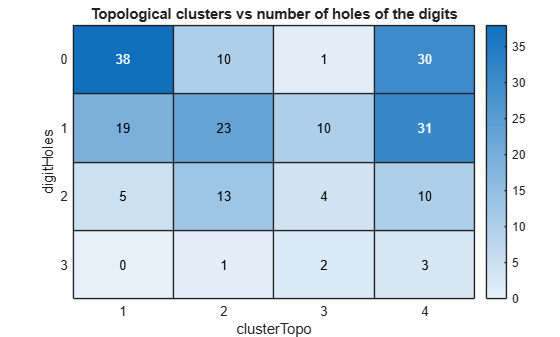


figure                                              % new figure
heatmap(T, "clusterTopo", "digitHoles");            % number of sequences of each hole class in each cluster
title("Topological clusters vs number of holes of the digits")  % title of the plot

The most typical animation of each cluster (closest to its topological mean)

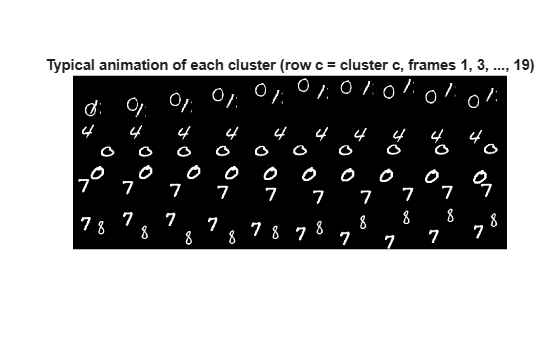

shownFrames = 1:2:numFrames;                        % frames 1, 3, 5, ..., 19
typicalFrames = zeros(numRows, numCols, 1, numel(shownFrames) * k, "uint8");  % shown frames of the typical animation of each cluster
for c = 1:k                                         % loop over the clusters
    [~, typical] = min(distToMean(:, c));           % sequence closest to the topological mean of cluster c
    typicalFrames(:,:,1,(c-1)*numel(shownFrames) + (1:numel(shownFrames))) = X(:,:,shownFrames,chosenSeq(typical));  % put its frames in row c
end                                                 % end of the loop over clusters
figure                                              % new figure
montage(typicalFrames, "Size", [k numel(shownFrames)]);  % k rows of 10 frames
title("Typical animation of each cluster (row c = cluster c, frames 1, 3, ..., 19)")  % title of the plot

d_top over time: single linkage clustering = graph filtration on the animations [768-TDA.pdf p.18], and a 2D map by multidimensional scaling [768-wasserstein.pdf p.21]

bettiOverTime = [numComp numHol];                   % persistent Betti numbers of the 20 frames
dTopTime = pdist(bettiOverTime, "cityblock");       % sum over frames of d_top(A_t, B_t)
clusterSingle = cluster(linkage(dTopTime, "single"), "maxclust", k);  % single linkage tree, cut into k clusters
singleLinkageSizes = groupcounts(clusterSingle)'    % number of animations in each cluster

singleLinkageSizes =      1   197     1     1


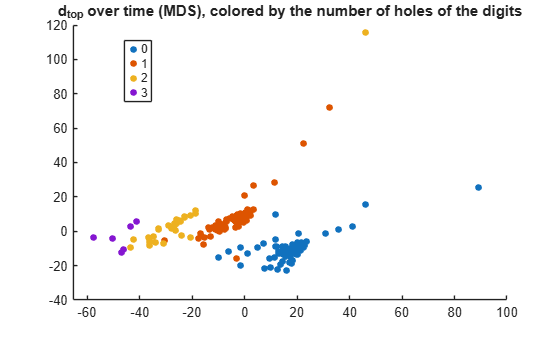


Y = cmdscale(squareform(dTopTime), 2);              % 2D points that keep the d_top distances
figure                                              % new figure
gscatter(Y(:,1), Y(:,2), digitHoles)                % one dot per animation, colored by its hole class
title("d_{top} over time (MDS), colored by the number of holes of the digits")  % title of the plot


% Result:
% - The topological clusters (Wasserstein over time) follow the stroke size of
%   the digits (purity 0.92). They are only weakly associated with the digit
%   holes: purity 0.51, while putting all sequences in one group already gives
%   0.42 (the largest class, 1 hole). Clusters with small strokes have fewer
%   holes on average (0.47) than clusters with large strokes (1.41), because
%   digits with holes (0, 6, 8, 9) have more ink.

% - Single linkage on d_top over time puts 197 of the 200 animations in one
%   cluster: the "chaining" of single linkage, since most animations differ
%   from some other animation by only one change of topology in one frame.

% - The MDS map of d_top over time shows the 4 hole classes in 4 different
%   regions, so d_top over time does separate the digit topology (expected in
%   part, since the hole classes are counted from the same Betti numbers), but
%   neither clustering method from the slides recovers these groups.

Learning Outcomes

By completing this project, students will gain a concrete understanding of how images can be modeled as cubical complexes and how filtrations encode geometric and topological information. They will learn how Betti numbers describe meaningful structural features such as connected components and holes, and how these features change across filtrations.

Students will also learn how to design topology-aware distances for both static and dynamic data and how to apply these distances to unsupervised learning problems such as clustering. The project will develop intuition for why topological methods can be robust to noise and deformation and how topology provides a complementary perspective to traditional pixel-based or statistical methods for analyzing complex, time-varying data.